# Anomalous Trichromatic Observer

% setup constant
display = load('display.mat');
prior   = load('sparsePrior.mat');

imageSize = [64, 64, 3];

retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 0.6, 'display', display.CRT12BitDisplay, 'pupilSize', 2.5);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 135.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.467435, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 135.00 137.42 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

% use plotlab style plots
% instantiate a plotlab object
plotlabOBJ = plotlab();
%
% apply the default plotlab recipe
% overriding just the figure size
plotlabOBJ.applyRecipe(...
    'figureWidthInches', 8, ...
    'figureHeightInches', 5);

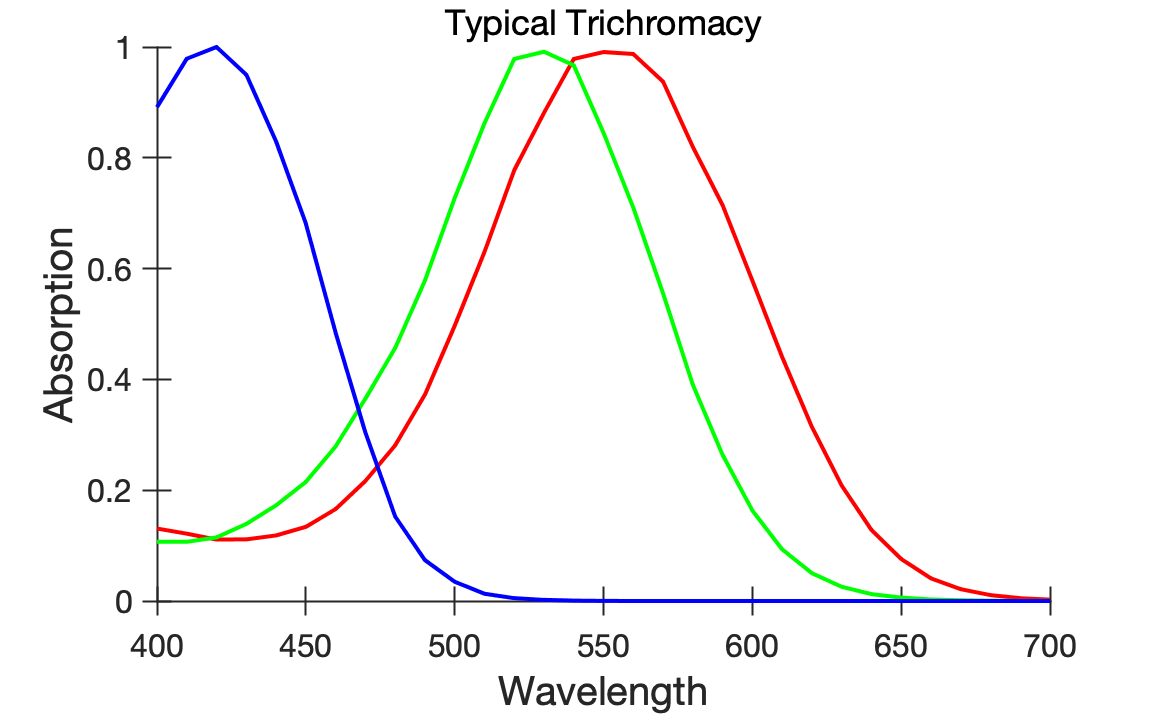

% plot spectral sensitivity
% get the pigment object
pigment = retina.Mosaic.pigment;

figure(); hold on;
colorSeq = ['r', 'g', 'b'];
for idx = 1 : length(colorSeq)
    % plot absorbance against wavelength
    plot(pigment.wave, pigment.absorbance(:, idx), 'LineWidth', 2, 'Color', colorSeq(idx));    
end

xlabel('Wavelength');
ylabel('Absorption');
title('Typical Trichromacy');
grid off; box off;

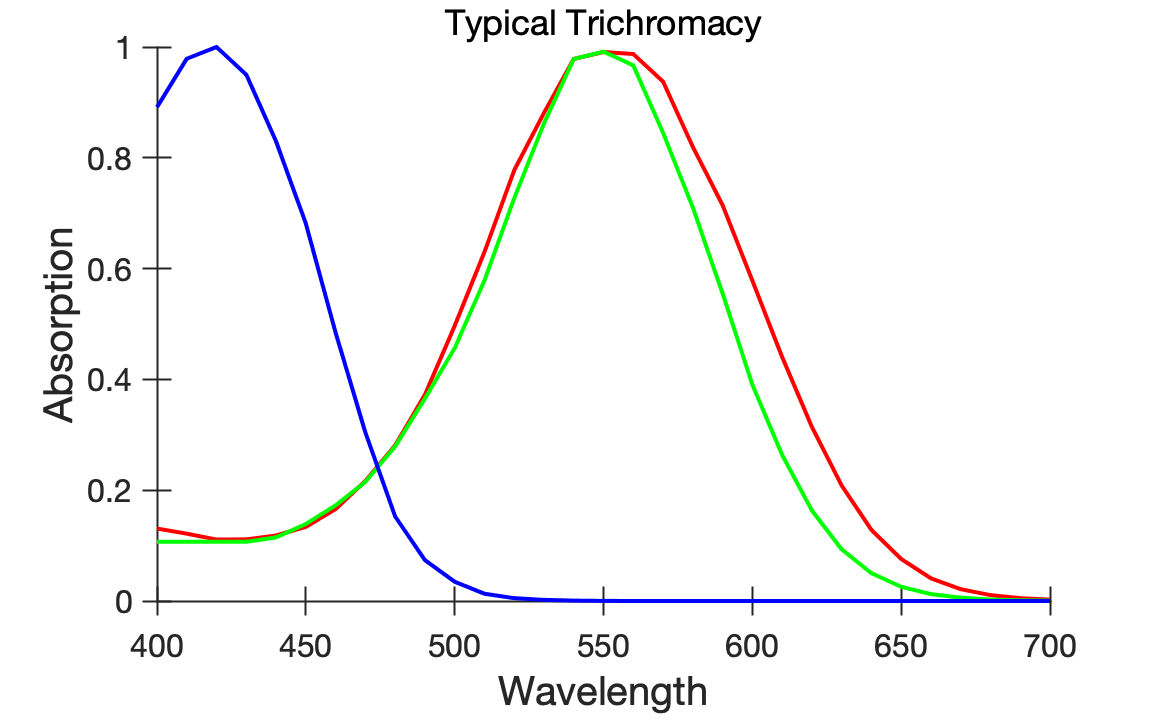

% shift M cone spectral sensitivity

% since the step size for wavelength is 10 nm, 
% a index displacement of 2 equals a 20 nm shift
% on the wavelength axis

shift = 2;
mCone = pigment.absorbance(:, 2);
anomMcone = pigment.absorbance(:, 2);

anomMcone(1+shift : end) = mCone(1 : end-shift);
anomMcone(1 : shift) = mCone(1 : shift);

% assign the new spectral sensitivity to pigment object
retina.Mosaic.pigment.absorbance(:, 2) = anomMcone;

% plot
pigment = retina.Mosaic.pigment;

figure(); hold on;
colorSeq = ['r', 'g', 'b'];
for idx = 1 : length(colorSeq)
    % plot absorbance against wavelength
    plot(pigment.wave, pigment.absorbance(:, idx), 'LineWidth', 2, 'Color', colorSeq(idx));    
end

xlabel('Wavelength');
ylabel('Absorption');
title('Typical Trichromacy');
grid off; box off;